# Visualize results of FD modeling

## Introduction

This script plots snapshots of the wavefield generated by FD code. 

**Author**: Abakumov Ivan

Freie Universität Berlin

**Publication date**: 22nd September 2017

**E-mail**: [abakumov_ivan@mail.ru](mailto:abakumov_ivan@mail.ru)

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Set parameters of FD modeling

folder = [mlibfolder '/Examples/Heidimod/s90900/'];
vp = 4000;                  % velocity of P-wave
vs = 2350;                  % velocity of S-wave
rho = 3000;                 % dencity 
ns = 130;                   % number of time samples
nts = 20;                   % number of time samples of the wavelet
dt = 0.002;                 % time step
nrec = 8;                   % number of receivers
f = 40;                     % dominant frequency

## Make G-file

G=GridClass;

% [m]        [m]          [m]          [s]
G.x0=0;      G.y0=0;      G.z0=0;      G.t0 = 0.00;        % initial point
G.nx=102;    G.ny=103;    G.nz=101;    G.nt = ns;          % grid size
G.dx=10;     G.dy=10;     G.dz=10;     G.dt = dt;          % grid step (meter)

G.gridInfo;

Information about grid:
x0=0, dx=10, Nx=102.
y0=0, dy=10, Ny=103.
z0=0, dz=10, Nz=101.
t0=0, dt=0.002, Nt=130.


G.setGrid;
Gold = oldGrid(G);

## Read results of FD modeling: source and receiver positions

fid = fopen([folder 'slocation'],'r');
sloc = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);

fid = fopen([folder 'geoloc'],'r');
gloc = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);
gloc = reshape(gloc,[3,nrec]);

acq.gsx = sloc(2,:); 
acq.gsy = sloc(3,:); 
acq.gsz = sloc(1,:);
acq.grx = gloc(2,:); 
acq.gry = gloc(3,:); 
acq.grz = gloc(1,:);
acq.sx = G.x0 + (acq.gsx-1)*G.dx;
acq.sy = G.y0 + (acq.gsy-1)*G.dy;
acq.sz = G.z0 + (acq.gsz-1)*G.dz;
acq.rx = G.x0 + (acq.grx-1)*G.dx;
acq.ry = G.y0 + (acq.gry-1)*G.dy;
acq.rz = G.z0 + (acq.grz-1)*G.dz;

clear sloc gloc

## Read results of FD modeling - snapshots

fid = fopen([folder 'xsnap'],'r');
datax = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);
datax = reshape(datax,[G.nz G.nx G.ny 1]);

fid = fopen([folder 'ysnap'],'r');
datay = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);
datay = reshape(datay,[G.nz G.nx G.ny 1]);

fid = fopen([folder 'zsnap'],'r');
dataz = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);
dataz = reshape(dataz,[G.nz G.nx G.ny 1]);

## Plot x-component of the wavefield

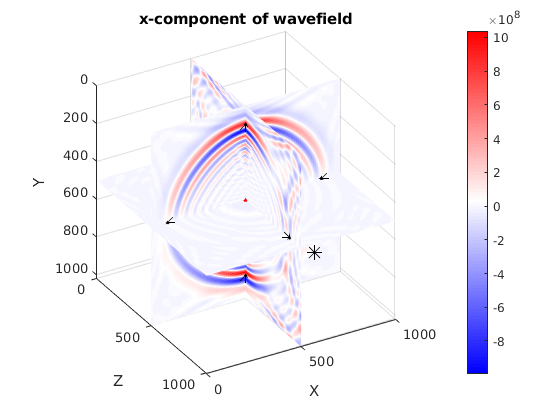

figure(1)
h=slice(G.xx,G.zz,G.yy,datax,acq.sx,acq.sz,acq.sy); 
hold on
plot3(acq.rz, acq.rx, acq.ry, 'k*', 'MarkerSize', 10);
plot3(acq.sz, acq.sx, acq.sy, 'r*', 'MarkerSize', 10);
set(h,'FaceColor','interp','EdgeColor','none','DiffuseStrength',.8)
xlabel('Z')
ylabel('X')
zlabel('Y')
axis ([G.x0 G.mx G.z0 G.mz G.y0 G.my]);
set(gca,'Zdir','reverse'); axis image;
view(60,30);
title('x-component of wavefield')
colorbar;
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

## Plot y-component of the wavefield

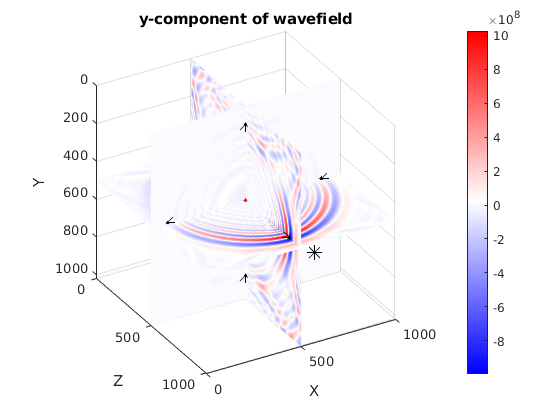

figure(2)
h=slice(G.xx,G.zz,G.yy,datay,acq.sx,acq.sz,acq.sy); 
hold on
plot3(acq.rz, acq.rx, acq.ry, 'k*', 'MarkerSize', 10);
plot3(acq.sz, acq.sx, acq.sy, 'r*', 'MarkerSize', 10);
set(h,'FaceColor','interp','EdgeColor','none','DiffuseStrength',.8)
xlabel('Z')
ylabel('X')
zlabel('Y')
axis ([G.x0 G.mx G.z0 G.mz G.y0 G.my]);
set(gca,'Zdir','reverse'); axis image;
view(60,30);
title('y-component of wavefield')
colorbar;
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

## Plot z-component of the wavefield

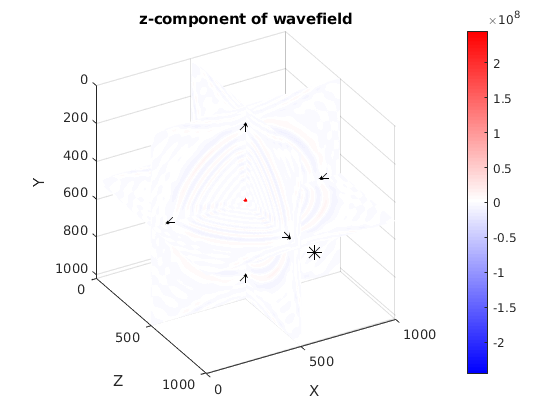

figure(3)
h=slice(G.xx,G.zz,G.yy,dataz,acq.sx,acq.sz,acq.sy); 
hold on
plot3(acq.rz, acq.rx, acq.ry, 'k*', 'MarkerSize', 10);
plot3(acq.sz, acq.sx, acq.sy, 'r*', 'MarkerSize', 10);
set(h,'FaceColor','interp','EdgeColor','none','DiffuseStrength',.8)
xlabel('Z')
ylabel('X')
zlabel('Y')
axis ([G.x0 G.mx G.z0 G.mz G.y0 G.my]);
set(gca,'Zdir','reverse'); axis image;
view(60,30);
title('z-component of wavefield')
colorbar;
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));